clear
clearAllMemoizedCaches
FFTSize = 4096;
hopSize = 2048;
wav = 'AudioTest\MEDASIN_midi_MEDASIN_midi_loop_epic_lead_C#min.wav'

wav = 'AudioTest\MEDASIN_midi_MEDASIN_midi_loop_epic_lead_C#min.wav'

Computing miraudio related to AudioTest\MEDASIN_midi_MEDASIN_midi_loop_epic_lead_C#min.wav...
Computing mirsum related to AudioTest\MEDASIN_midi_MEDASIN_midi_loop_epic_lead_C#min.wav...
Elapsed time is 0.569324 seconds.
 
audio is the Audio waveform related to AudioTest\MEDASIN_midi_MEDASIN_midi_loop_epic_lead_C#min.wav, of sampling rate 48000 Hz.


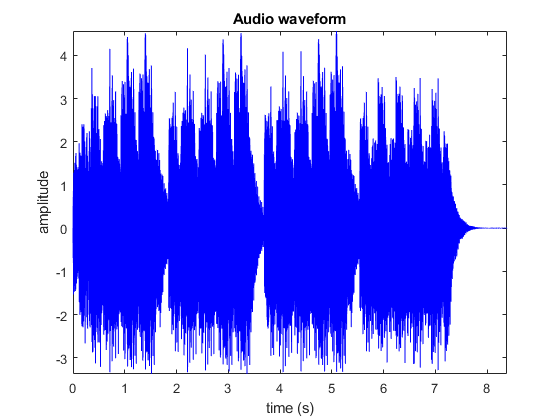

Its content is displayed in Figure 1.
 


audio = miraudio(wav,'Normal')

Computing mirfilterbank related to AudioTest\MEDASIN_midi_MEDASIN_midi_loop_epic_lead_C#min.wav...
 
filterBank is the Audio waveform related to AudioTest\MEDASIN_midi_MEDASIN_midi_loop_epic_lead_C#min.wav, of sampling rate 48000 Hz.


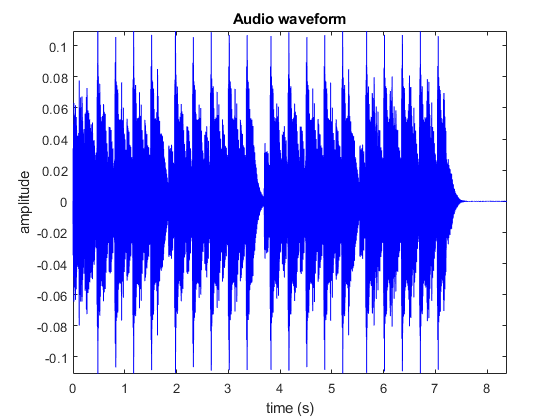

Its content is displayed in Figure 2.
 


filterBank = mirfilterbank(audio,'Gammatone','Channel',7)

frame = mirframe(filterBank,FFTSize,'sp',hopSize,'sp');


Computing mirspectrum related to AudioTest\MEDASIN_midi_MEDASIN_midi_loop_epic_lead_C#min.wav...
 
spectre is the Power Spectrum related to AudioTest\MEDASIN_midi_MEDASIN_midi_loop_epic_lead_C#min.wav, of sampling rate 48000 Hz.


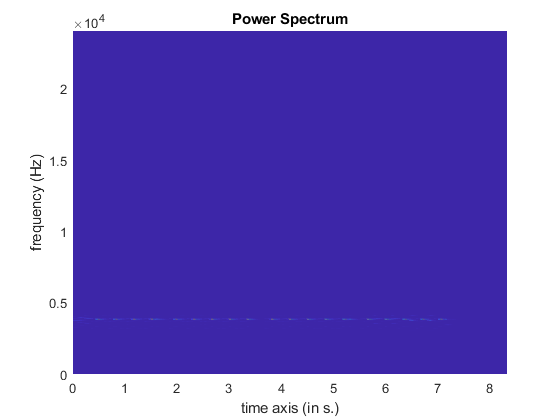

Its content is displayed in Figure 3.
 


spectre = mirspectrum(filterBank,'Frame',FFTSize,'sp',hopSize,'sp','Terhardt','Power')

Computing mirflux related to AudioTest\MEDASIN_midi_MEDASIN_midi_loop_epic_lead_C#min.wav...
 


The Spectral flux related to file AudioTest\MEDASIN_midi_MEDASIN_midi_loop_epic_lead_C#min.wav is displayed in Figure 4.


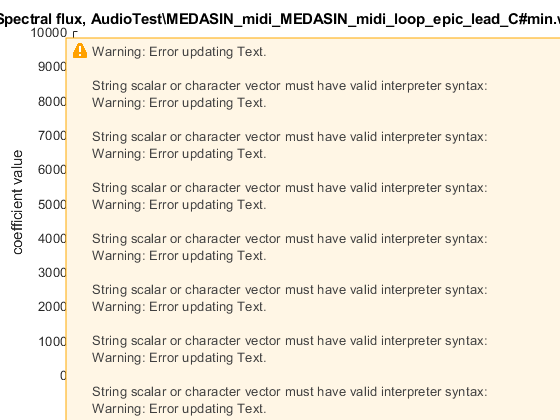


flux = mirflux(spectre,'Median','Inc','Halfwave')

fluxdata = mirgetdata(flux);
fluxdata(:,:,1)

ans = 	1.0e+03 *

         0         0         0         0    0.2772    0.3011         0         0         0    5.3311    2.0495         0         0         0         0    0.3517         0    3.8645    4.4500         0         0         0         0    0.3184         0    2.3642    6.3279         0         0         0         0    0.2726         0    1.1597    7.8284         0    1.3147    2.3662         0         0         0         0    0.4403         0    3.5251    5.1919         0         0         0         0


Computing mirenvelope related to AudioTest\MEDASIN_midi_MEDASIN_midi_loop_epic_lead_C#min.wav...
 
enveloppe is the Differentiated envelope (half-wave rectified) related to AudioTest\MEDASIN_midi_MEDASIN_midi_loop_epic_lead_C#min.wav, of sampling rate 3000 Hz.


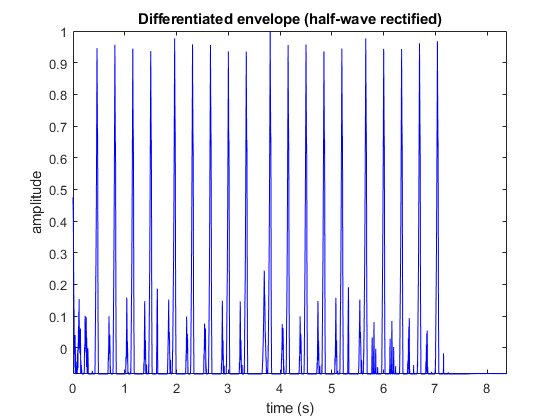

Its content is displayed in Figure 5.
 


%methode de suiveur envelope avec peak picking
enveloppe = mirenvelope(filterBank, 'FilterType', 'IIR','HalfwaveCenter','Diff','Normal','Center')

Computing mirpeaks related to AudioTest\MEDASIN_midi_MEDASIN_midi_loop_epic_lead_C#min.wav...
 
envelopepeaks is the Differentiated envelope (half-wave rectified) related to AudioTest\MEDASIN_midi_MEDASIN_midi_loop_epic_lead_C#min.wav, of sampling rate 3000 Hz.


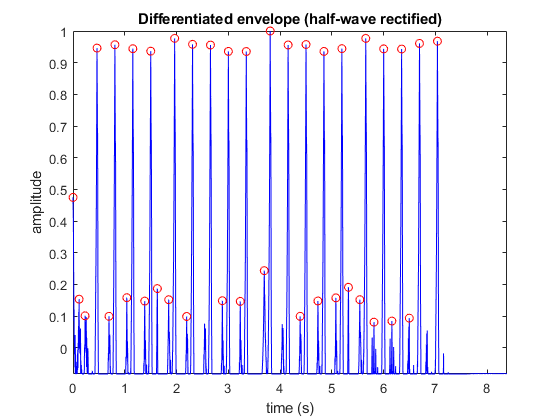

Its content is displayed in Figure 6.
 


envelopepeaks = mirpeaks(enveloppe,'Threshold',0.15,'Reso',0.07)


envelopedata =  mirgetdata(envelopepeaks);
envelopedataSort = sort(envelopedata);
envelopedataSort = sort(envelopedata(:,:,1))

envelopedataSort =     0.0010
    0.1186
    0.2333
    0.4635
    0.6955
    0.8092
    1.0392
    1.1556
    1.3852
    1.5016


 
segment is the Audio waveform related to AudioTest\MEDASIN_midi_MEDASIN_midi_loop_epic_lead_C#min.wav, of sampling rate 48000 Hz.


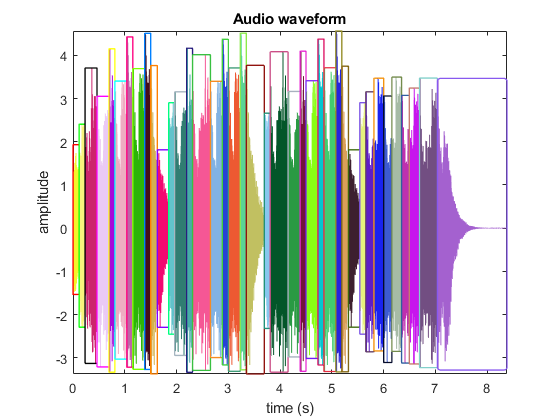

Its content is displayed in Figure 7.
 


segment = mirsegment(audio,envelopepeaks)

Computing mirfilterbank related to AudioTest\MEDASIN_midi_MEDASIN_midi_loop_epic_lead_C#min.wav...
Computing mirautocor related to AudioTest\MEDASIN_midi_MEDASIN_midi_loop_epic_lead_C#min.wav...
Computing mirsum related to AudioTest\MEDASIN_midi_MEDASIN_midi_loop_epic_lead_C#min.wav...
Computing mirautocor related to AudioTest\MEDASIN_midi_MEDASIN_midi_loop_epic_lead_C#min.wav...
Computing mirpeaks related to AudioTest\MEDASIN_midi_MEDASIN_midi_loop_epic_lead_C#min.wav...
Computing mirpeaks related to AudioTest\MEDASIN_midi_MEDASIN_midi_loop_epic_lead_C#min.wav...
Computing mirautocor related to AudioTest\MEDASIN_midi_MEDASIN_midi_loop_epic_lead_C#min.wav...
Computing mirpitch related to AudioTest\MEDASIN_midi_MEDASIN_midi_loop_epic_lead_C#min.wav...
Computing mirpeaks related to AudioTest\MEDASIN_midi_MEDASIN_midi_loop_epic_lead_C#min.wav...
 


The Pitch related to file AudioTest\MEDASIN_midi_MEDASIN_midi_loop_epic_lead_C#min.wav is displayed in Figure 8.


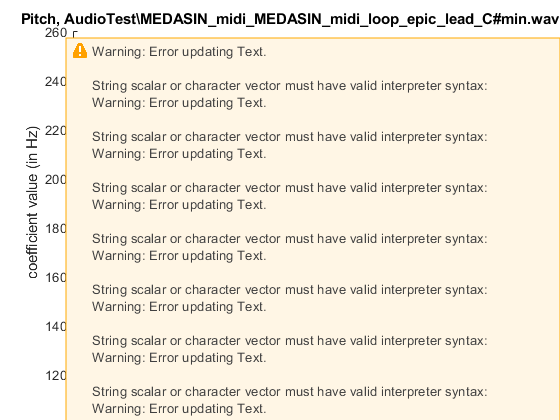

pitch = mirpitch(segment)

mirgetdata(pitch)

ans =        NaN  139.2480       NaN       NaN  188.3107  207.9766  209.9227  207.9975  209.8270  208.0911  213.8163       NaN  209.4981  188.2168  208.2797  186.9717  209.9003  207.8877  209.8306  208.0602       NaN  209.2429  187.4867  187.8846  208.4661  209.8813  207.9961  209.7259  208.0425  209.6722       NaN  209.5082  245.3787  211.3353       NaN  211.4513       NaN  208.8702       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN  247.5868       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN  208.0626       NaN       NaN       NaN       NaN       NaN       NaN  247.8273       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
